# TP #09 - Ejercicio 07

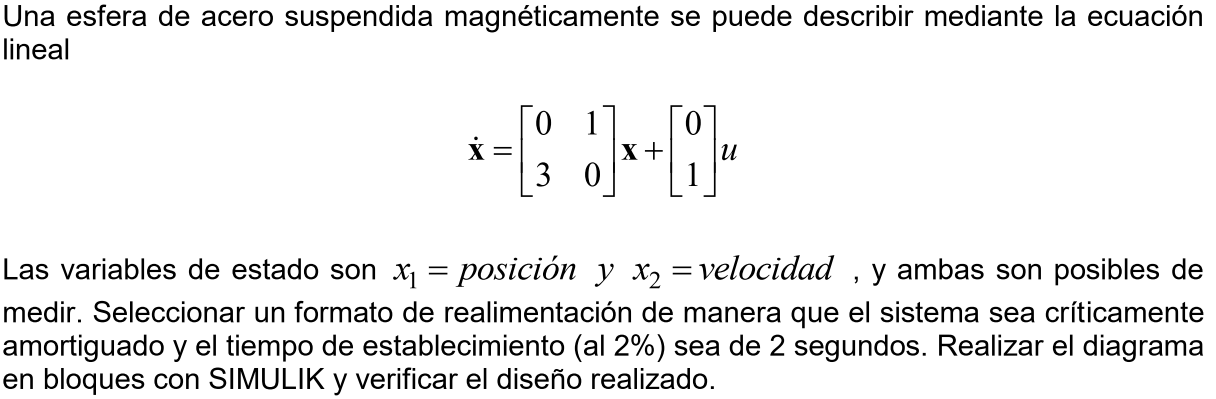

Se pide,

- 
$$\xi =1$$


- 
$$t_s =2$$


Recordando que,

$t_s \approx \frac{5\ldotp 83}{\xi w_n }$, $\xi w_n \approx \frac{5\ldotp 83}{2}$,


$$\xi w_n \approx 2\ldotp 91$$


Como el factor de amortiguamiento es unitario, se desprende de esta condición que estamos ante un amortiguamiento crítico, es decír los polos deben ser reales e iguales.

${\left(s+\xi w_n \right)}^2 =s^2 +5\ldotp 83s+8\ldotp 47$; **(a)**

Con estos datos busquemos entonces la matríz 'K'


$$\begin{array}{l}
\mu \left(t\right)=-\mathrm{KX}\left(t\right)\\
\overset{\ldotp }{X} \left(t\right)=\mathrm{AX}\left(t\right)+B\mu \left(t\right)\\
\overset{\ldotp }{X} \left(t\right)=\mathrm{AX}\left(t\right)+B\left(-\mathrm{KX}\left(t\right)\right)\\
\overset{\ldotp }{X} \left(t\right)=\left(A-\mathrm{BK}\right)X\left(t\right)
\end{array}$$


Quedando entonces,


$$\begin{array}{l}
A-\textrm{BK}=\left\lbrack \begin{array}{cc}
0 & 1\\
3 & 0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
k_1  & k_2 
\end{array}\right\rbrack \\
A-\textrm{BK}=\;\left\lbrack \begin{array}{cc}
0 & 1\\
3 & 0
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
0 & 0\\
k_1  & k_2 
\end{array}\right\rbrack \\
A-\textrm{BK}=\;\left\lbrack \begin{array}{cc}
0 & 1\\
3-k_1  & -k_2 
\end{array}\right\rbrack 
\end{array}$$


Finalmente hallamos la expresión de los polos deseados,


$$\begin{array}{l}
\left(\textrm{sI}-A+\textrm{BK}\right)=\left\lbrack \begin{array}{cc}
s & 0\\
0 & s
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
0 & 1\\
{3-k}_1  & -k_2 
\end{array}\right\rbrack \\
\left(\textrm{sI}-A+\textrm{BK}\right)=\left\lbrack \begin{array}{cc}
s & -1\\
k_1 -3 & s+k_2 
\end{array}\right\rbrack 
\end{array}$$


Hallamos ahora el determinante,


$$\textrm{det}\left(\textrm{sI}-A+\textrm{BK}\right)=s^2 +{s\;k}_2 +k_1 -3$$


Reemplazando con lo hallado en **(a)**

- 
$$k_1 =11\ldotp 47$$


- 
$$k_2 =5\ldotp 83$$


Se puede considerar el sistema como un regulador ya que la esfera está suspendida,

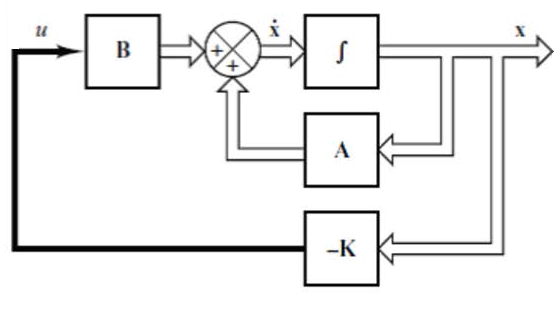

Por lo tanto debemos utilizar el comando 'initial' para poder simular la respuesta del mismo.

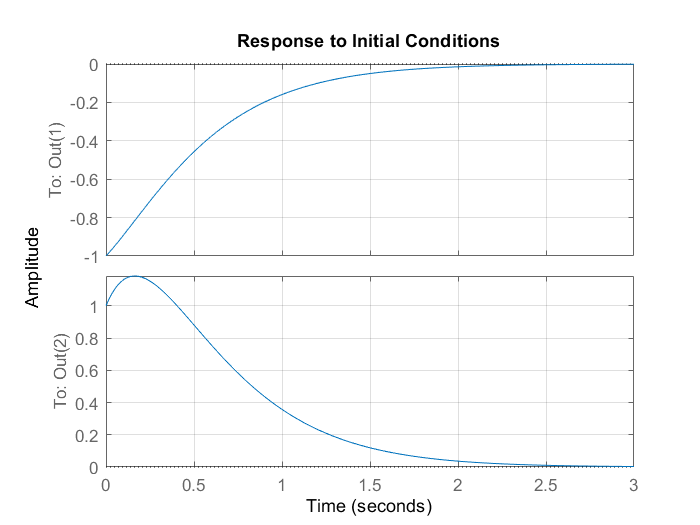

An = [0 1; -8.47 -5.83];    % Matriz 'An = (A-BK)' obtenida.
C = [1 0; 0 1];             % Queremos obtener la posición y velocidad de nuestro sistema.
X0 = [-1 1];                % x0 = -1m; v0 = 1m/s;
sys = ss(An, [], C, []);    % Sistema regulador.
initial(sys, X0);
grid on;

El mismo comportamiento lo podemos observar en Simulink, ejecutar ***TP09_ej07.slx.***

Notar que las condiciones iniciales están cargadas en los integradores.